# Plot Figure 2 - Supplementary Figure 6

## Add path

addpath(genpath('../public_code'));

## Load data

nstrain = 'male_before_timp_180511'; nNodes = 15;

%%
didf2 = {};
didf2{end+1} = [0:9; 0:9]';
didf2{end+1} = [0:2:9; 1:2:9]';
didf2{end+1} = [0:3:8; 2:3:9]';
didf2{end+1} = [0:4:7; 3:4:9]';
didf2{end+1} = [0, 4; 5, 9];
didf2{end+1} = [0, 9];


log10_beta_G2 = -1:0.5:1;
beta_G2 = 10.^log10_beta_G2;
%%

## Plot Figure 2 - Supplementary Figure 5: cross-validation of triplet maximum entropy model with L2 regularization learned from 10 day aggregation of the data 

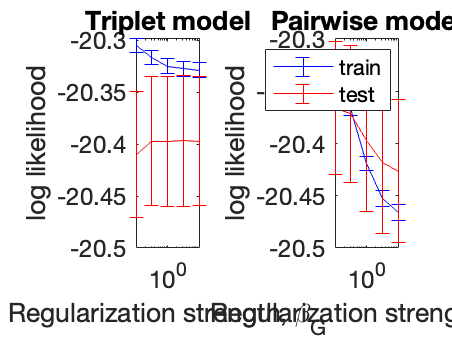

di = 0; df = 9;
ttscheme = '1h';
[ntest_max] = fix_ntest_max(ttscheme, di, df);


shift_flag = 0;

figure()
subplot(1,2,1)
[logZ3_t] = ...
    load_ZS_triplet(nstrain, di, df, ttscheme, beta_G2);
[ll_test2_t, ll_train2_t] = ...
    load_ll_triplet(nstrain, di, df, ttscheme);
plot_ll(beta_G2, ll_train2_t, ll_test2_t, logZ3_t, ntest_max, shift_flag);
xlabel('Regularization strength, \beta_G')
ylabel('log likelihood')
title('Triplet model')

subplot(1,2,2)
[logZ3_p] = load_ZS_pairwise(nstrain, di, df, ttscheme);
[ll_test2_p, ll_train2_p] = ...
    load_ll_pairwise(nstrain, di, df, ttscheme);
plot_ll(beta_G2, ll_train2_p, ll_test2_p, logZ3_p, ntest_max, shift_flag);
xlabel('Regularization strength, \beta_J')
ylabel('log likelihood')
title('Pairwise model')
legend('train','test')

%%




## Plot Figure 2 - Supplementary Figure 6: cross-validation of pairwise maximum entropy model with L2 regularization learned from aggregation of K days

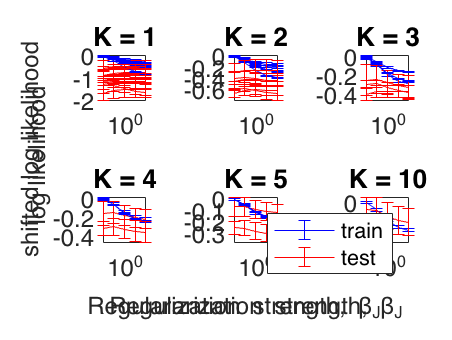


figure()
t = tiledlayout(2,3);
for k = 1:6
    nexttile;
    for i = 1:size(didf2{k},1)
        di = didf2{k}(i,1);
        df = didf2{k}(i,2);
        %%
        ttscheme = '1h';
        [ntest_max] = fix_ntest_max(ttscheme, di, df);
       

        [logZ3_p] = load_ZS_pairwise(nstrain, di, df, ttscheme);
        [ll_test2_p, ll_train2_p] = ...
            load_ll_pairwise(nstrain, di, df, ttscheme);

        shift_flag = 1;
        plot_ll(beta_G2, ll_train2_p, ll_test2_p, logZ3_p, ntest_max, shift_flag);
        hold on

    end


    title(['K = ' num2str(df-di+1)] )
end
legend('train','test')
%%
set(gca,'fontsize',12)
xlabel(t, 'Regularization strength, \beta_J')
ylabel(t, 'shifted log likelihood')

function [ntest_max] = fix_ntest_max(ttscheme, di, df)

    switch ttscheme
        case '1h'
            ntest_max = 6;
        case '1day'
            ntest_max = df-di+1;
        otherwise
            error('ttscheme has to be 1h or 1day')
    end
end

function [logZ3, logEZ3, S3] = load_ZS_triplet(nstrain, di, df, ttscheme, beta_G2)

[ntest_max] = fix_ntest_max(ttscheme, di, df);

logZ3 = zeros(ntest_max, length(beta_G2));
logEZ3 = zeros(ntest_max, length(beta_G2));
S3 = zeros(ntest_max, length(beta_G2));


for ibeta = 1:length(beta_G2)
    %%
    fp_new = ['computes_triplet_l2_' nstrain '_di' num2str(di) ...
        '_df' num2str(df) '_' ttscheme ...
        '_ibeta' num2str(ibeta) '.mat'];
    load(fp_new, 'logZ2','logEZ2','S2');

    logZ3(:, ibeta) = logZ2;
    logEZ3(:, ibeta) = logEZ2;
    S3(:, ibeta) = S2;

end

end

function [ll_test2, ll_train2] = load_ll_triplet(nstrain, di, df, ttscheme)

% notice here the log likelihood is not the complete one, it's the one
% before subtracting log Z

fp_ll = ['computell_triplet_l2_' nstrain '_di' num2str(di) ...
    '_df' num2str(df) '_' ttscheme '.mat'];
load(fp_ll, 'll_test_list2','ll_train_list2');
ll_test2 = ll_test_list2;
ll_train2 = ll_train_list2;

end

function [logZ3, logEZ3, S3] = load_ZS_pairwise(nstrain, di, df, ttscheme)

fp_pairwise = ['computes_pairwise_l2_' nstrain '_di' num2str(di) ...
    '_df' num2str(df) '_' ttscheme '.mat'];
load(fp_pairwise, 'logZ3','logEZ3','S3');

end

function [ll_test2, ll_train2] = load_ll_pairwise(nstrain, di, df, ttscheme) 

fp_ll_pairwise = ['computell_pairwise_l2_' nstrain '_di' num2str(di) ...
    '_df' num2str(df) '_' ttscheme '.mat'];
load(fp_ll_pairwise, 'll_test_list2','ll_train_list2');
ll_test2 = ll_test_list2;
ll_train2 = ll_train_list2;


end

function plot_ll(beta_G2, ll_train2, ll_test2, logZ3, ntest_max, shift_flag)

if shift_flag 
    errorbar(beta_G2, ...
        mean(ll_train2 - logZ3) - mean(ll_train2(:,1) - logZ3(:,1)), ...
        std(ll_train2 - logZ3)/sqrt(ntest_max), 'b')
    hold on
    errorbar(beta_G2, ...
        mean(ll_test2 - logZ3) - mean(ll_train2(:,1) - logZ3(:,1)), ...
        std(ll_test2 - logZ3)/sqrt(ntest_max), 'r')
    hold off
else
    errorbar(beta_G2, ...
        mean(ll_train2 - logZ3), ...
        std(ll_train2 - logZ3)/sqrt(ntest_max), 'b')
    hold on
    errorbar(beta_G2, ...
         mean(ll_test2 - logZ3), ...
         std(ll_test2 - logZ3)/sqrt(ntest_max), 'r')
    hold off
end

set(gca,'xscale','log')
set(gca,'fontsize',12)

end
